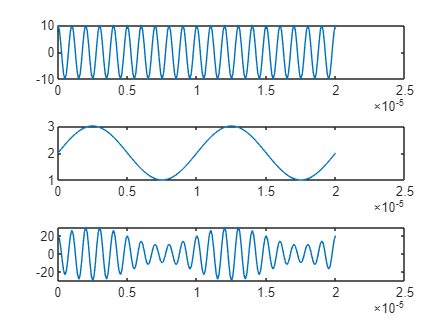

clear variables

t = 0 : 1e-7 : 2e-5;

Tc = 1e-6;
fc = 1 / Tc;
Ac = 10;
c = @(t) (Ac * cos(2 * pi * fc * t));
subplot(3, 1, 1);
plot(t, c(t));

Tx = 1e-5; % perioada pentru X
wx = 2 * pi / Tx; % viteza unghiulara pentru X
x = @(t) (sin(wx * t) + 2);
subplot(3, 1, 2);
plot(t, x(t));

s = @(t) (x(t) .* Ac .* cos(2 .* pi .* fc .* t));
subplot(3, 1, 3);
plot(t, s(t));

%{ 
Ex2
clear variables

t = -3 : 0.01 : 3;
u0 = @(t) (t>=0);
A = 2;
x = @(t) A*u0(t) .* (t>=0 & t<=2);
plot(t, x(t));

o = @(t) 1/2*(x(t)-x(-t));
plot(t, o(t));

t = -3 : 0.01 : 3;
u0 = @(t) (t>=0);
A = 2;
y = @(t) 2*t .* (t>=0 & t<=1) + (4-2*t) .* (t>1 & t<=2);
plot(t, y(t));

z = @(t) 1/2*(y(t)-y(-t));
plot(t, z(t));
%}